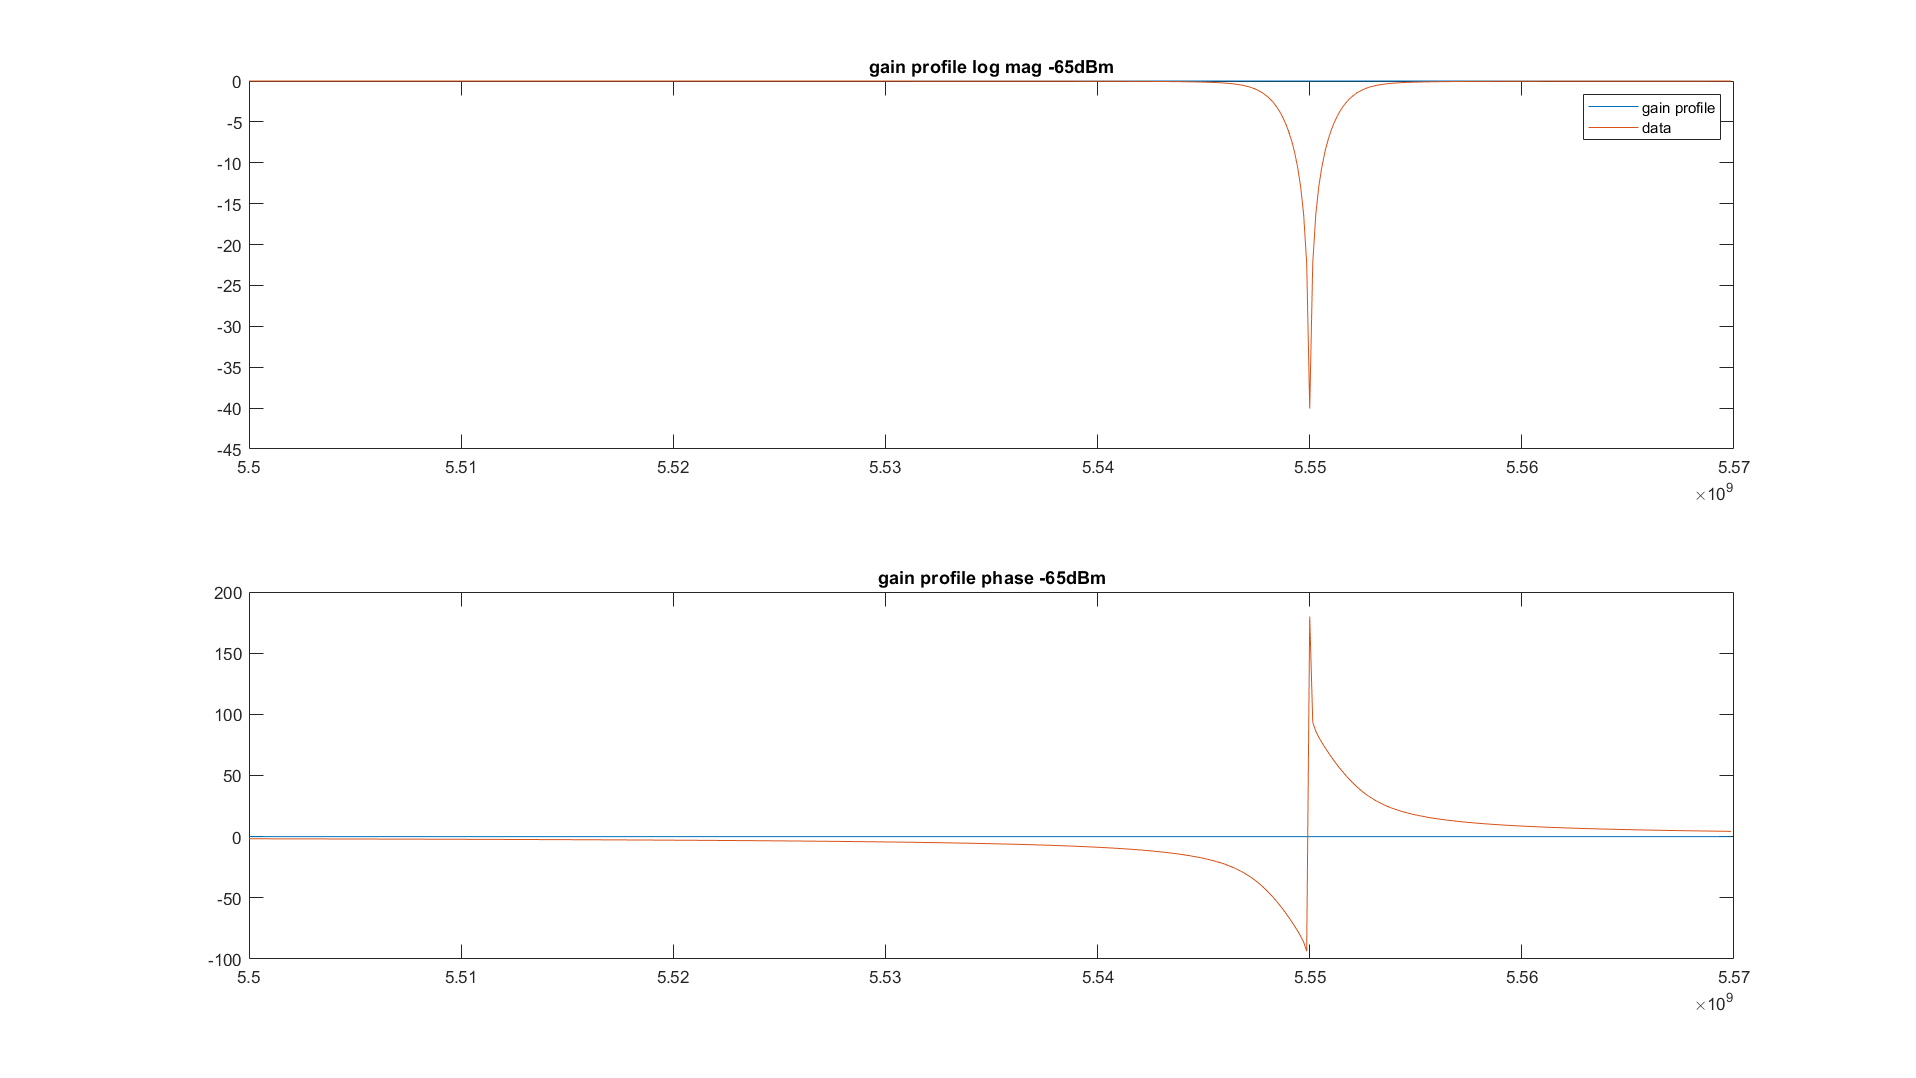

number_points = 701;
gain_prof_amp = zeros(number_points,1);
gain_prof_phase = zeros(number_points,1);
freqs = linspace(5.5e9,5.6e9,number_points);
gain_prof_freq = freqs;
kappa_ext = 1.5e6;
kappa_int = .4e6;
omega_0 = 5.55e9;
sigma = 1e6;
delta = freqs - omega_0;
omega_1 = 5.59e9;
p_omega_0 = 0.5;
 
kappa_tot = kappa_int + kappa_ext;

[s11_qp_omega_0_real, s11_qp_omega_0_imag] = q_circle_with_freq_flucs(freqs,kappa_int,kappa_ext,omega_0,sigma);
[s11_qp_omega_1_real, s11_qp_omega_1_imag] = q_circle_with_freq_flucs(freqs,kappa_int,kappa_ext,omega_1,sigma);
s11_qp_test_real = p_omega_0 * s11_qp_omega_0_real + (1-p_omega_0)*s11_qp_omega_1_real;
s11_qp_test_imag = p_omega_0 * s11_qp_omega_0_imag + (1-p_omega_0)*s11_qp_omega_1_imag;
[data_lin_mag_qp, data_phase_radians_qp] = extract_lin_mag_phase_from_real_imag(s11_qp_test_real,s11_qp_test_imag,freqs);
[data_log_mag_qp, data_phase_degs_qp] = extract_log_mag_phase_degs(data_lin_mag_qp, data_phase_radians_qp);

[s11_original_real, s11_original_imag]=q_circle_with_freq_flucs(freqs,kappa_int,kappa_ext,omega_0,sigma);
[data_lin_mag_original, data_phase_radians_original] = extract_lin_mag_phase_from_real_imag(s11_original_real,s11_original_imag,freqs);
[data_log_mag_original, data_phase_degs_original] = extract_log_mag_phase_degs(data_lin_mag_original, data_phase_radians_original);

plot_q_circles_and_save(gain_prof_freq(freqs<5.57e9),gain_prof_amp(freqs<5.57e9), ...
    gain_prof_phase(freqs<5.57e9),data_log_mag_original(freqs<5.57e9), ...
    data_phase_degs_original(freqs<5.57e9),freqs(freqs<5.57e9),0,'b','a',kappa_int,kappa_ext,sigma);

title('No QP "data" and fits')
plot_q_circles_and_save(gain_prof_freq(freqs<5.57e9),gain_prof_amp(freqs<5.57e9), ...
    gain_prof_phase(freqs<5.57e9),data_log_mag_qp(freqs<5.57e9),data_phase_degs_qp(freqs<5.57e9), ...
    freqs(freqs<5.57e9),0,'b','a',kappa_int,kappa_ext,sigma);
title(['with QP "data" and fits, fraction = ' num2str(p_omega_0)])


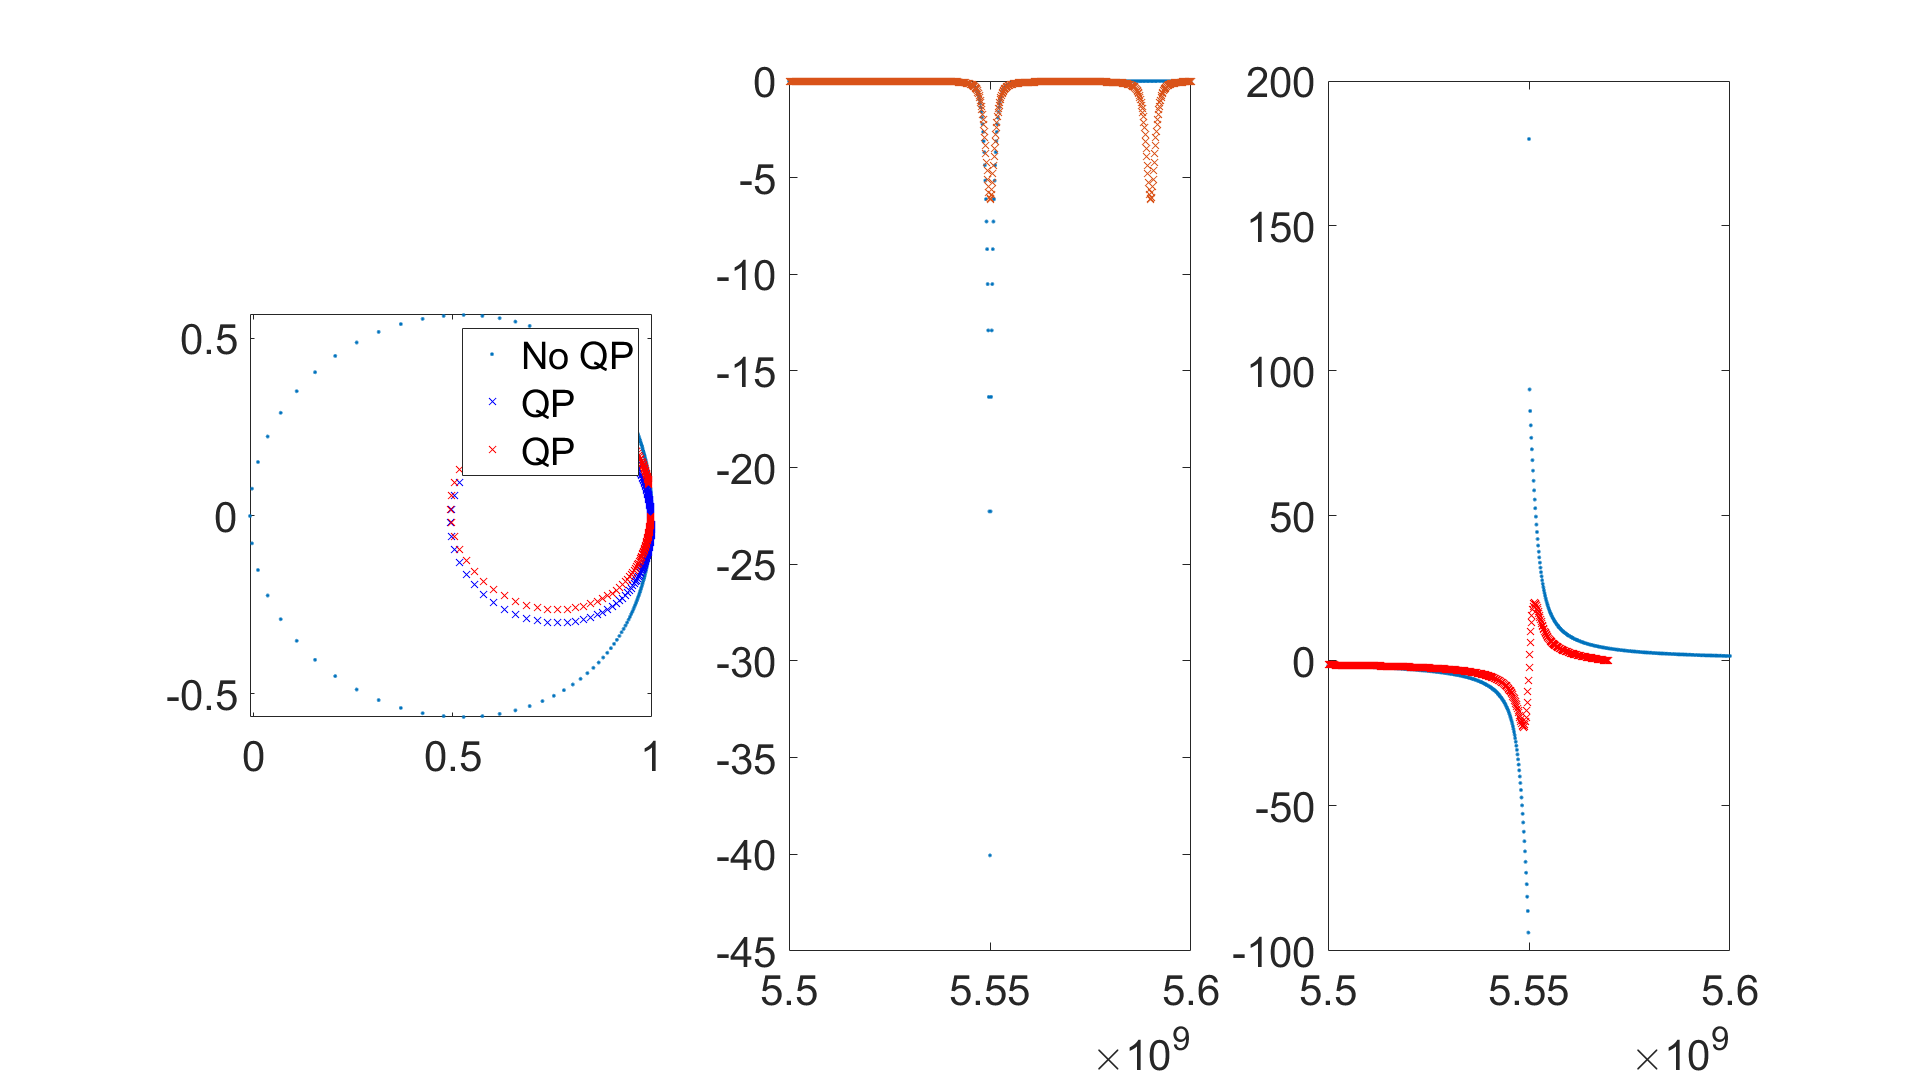

figure
subplot(1,3,1)
plot(s11_original_real, s11_original_imag,'.','DisplayName','No QP')
hold on
plot(s11_qp_test_real(freqs < 5.57e9),s11_qp_test_imag(freqs < 5.57e9),'bx','DisplayName','QP')
plot(s11_qp_test_real(freqs > 5.57e9),s11_qp_test_imag(freqs > 5.57e9),'rx','DisplayName','QP')
legend show
pbaspect([1 1 1])
subplot(1,3,2)
plot(freqs, data_log_mag_original, '.', 'DisplayName', 'No QP')
hold on
plot(freqs, data_log_mag_qp,'x', 'DisplayName', 'QP')
subplot(1,3,3)
plot(freqs, data_phase_degs_original, '.', 'DisplayName','No QP')
hold on
plot(freqs(freqs < 5.57e9), data_phase_degs_qp(freqs < 5.57e9),'rx','DisplayName','QP')

% plot(freqs(freqs > 5.57e9), data_phase_degs_qp(freqs < 5.57e9),'bx','DisplayName','QP')